% Load face images from a folder
imageDir = 'Faces/';
testimages = dir(fullfile(imageDir, 'db1*.jpg'));
numImages = numel(testimages);

% Read images into a cell array
faceData = cell(1, numImages);
for i = 1:numImages
    % Load your image
    img = im2double(imread(fullfile(imageDir, "db1_" + i + ".jpg")));
    [eye1, eye2] = findEyes(img);
    faceData{i} = faceNormalization(img, eye1, eye2);
end

Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.
Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds. Index must not exceed 1.



% Flatten each image into a vector
faceVectors = cellfun(@(x) x(:), faceData, 'UniformOutput', false);
% Combine faceVectors to form X (each row represents an image)
numPixels = numel(faceVectors{1}); % Number of pixels in each image

X = zeros(numPixels, numImages);

for i = 1:numImages
    X(:, i) = faceVectors{i}';
end

zeros()

ans = 0


mean_face = mean(X)

mean_face =     0.5000    0.4993    0.4993    0.5001    0.4989    0.4998    0.4999    0.5002    0.4997    0.5010    0.5013    0.5006    0.4994    0.5006    0.4996    0.4991


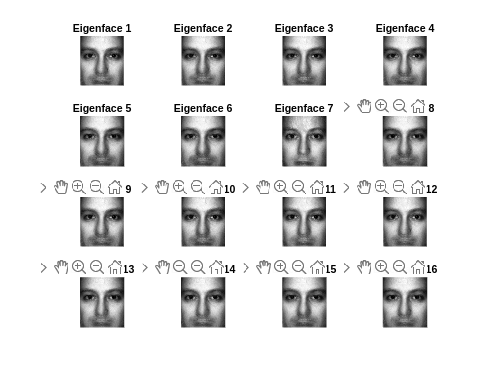


A = X - mean_face;

%C = A*A';
V = A'*A;

% Maby wrong might need to compute evey u seperatly
U = A*V;

[width, ~] = size(faceData{1});
figure;
for i = 1:16
   eigenface = reshape(U(:,i), width, []);
   subplot(4, 4, i);
   imshow(eigenface, []);
   title(['Eigenface ', num2str(i)]);
end


W = U'*A;

save("traind_model", 'mean_face', 'W');


